%các thông số đầu vào
A1 = 1; f1 = 2;
A2 = 2; f2 = 5;
A3 = 3; f3 = 8;
A4 = 4; f4 = 12;
fs = 72;
ts = 1/fs;


%thời gian để vẽ tín hiệu
t = 0:ts:5;
%các phương trình để đẩy ra phương trình tổng xn
x1 = A1*sin(2*pi*f1*t);
x2 = A2*sin(2*pi*f2*t);
x3 = A3*sin(2*pi*f3*t);
x4 = A4*sin(2*pi*f4*t);

xn = x1 + x2 + x3 + x4;

sigma_p = 0.02;
sigma_s = 0.02;
f_p = 1;
f_s = 2;
OMEGA_p = 2*pi*f_p;
OMEGA_s = 2*pi*f_s;


TS = log10(((1 - (1 - sigma_p) ^ 2) * sigma_s ^ 2) / (1 - sigma_p) ^ 2 * (1-sigma_s ^ 2) )

TS = -4.7829

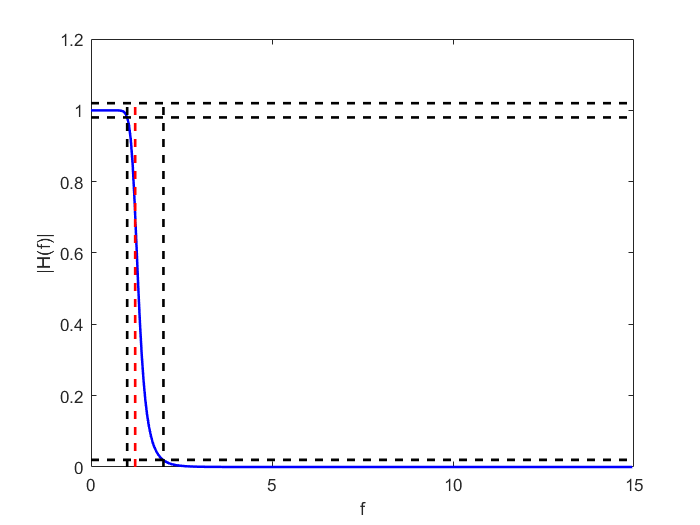

MS = log10(OMEGA_p/OMEGA_s);
N = (1/2)*(TS/MS); % Lấy bậc lọc theo công thức lý thuyết
N = fix(N) + 1; % Làm tròn bậc lọc

MS = ((1 - (1 - sigma_p)^2)/(1 - sigma_p)^2)^(1/(2*N));
OMEGA_c = OMEGA_p/MS;
f_c = OMEGA_c/(2*pi);

syms s sp u W w;
T = 1;
for i = 1:N
    si = OMEGA_c * exp(1i * ((2 * i + N - 1) / (2*N)) * pi);
    T = T*(s - si);
end
Ha_sTQ = (OMEGA_c ^ N) / T;
Ha_jW = subs(Ha_sTQ, 1i*W);

f = 0.001:1/20:15;
W_val = 2*pi*f;
Ha_jW = subs(Ha_jW, W_val);
Ha_jW = double(Ha_jW);

%vẽ lọc tham chiếu ban đầu
figure(1);
plot(f,abs(Ha_jW),'b-','linewidth',1.5);
line([0 15],[1-sigma_p 1-sigma_p],'Color','black','LineStyle','--','linewidth',1.6);
line([0 15],[1+sigma_p 1+sigma_p],'Color','black','LineStyle','--','linewidth',1.6);
line([0 15],[sigma_s sigma_s],'Color','black','LineStyle','--','linewidth',1.6);
line([f_p f_p],[0 1+sigma_p],'Color','black','LineStyle','--','linewidth',1.6);
line([f_s f_s],[0 1+sigma_p],'Color','black','LineStyle','--','linewidth',1.6);
line([f_c f_c],[0 1+sigma_p],'Color','red','LineStyle','--','linewidth',1.6);
xlabel('f'); ylabel('|H(f)|');

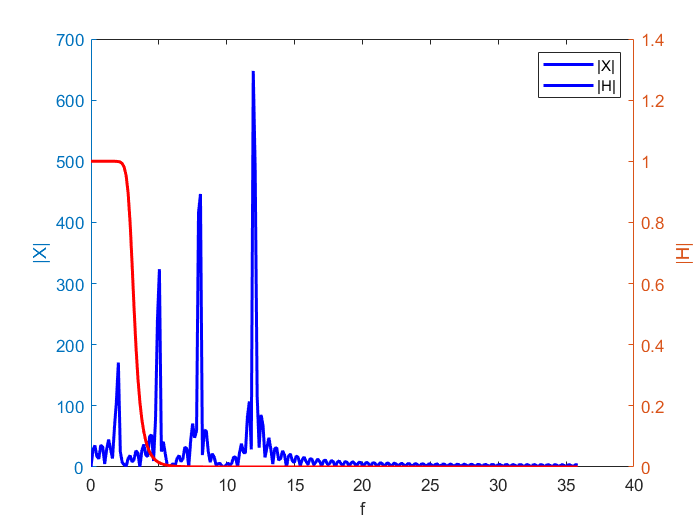


 %thông số các lọc thấp qua và thiết kế lọc thấp qua
fc_p1 = 3;
OMEGAc_p = 2*pi*fc_p;
s = (OMEGA_c / OMEGAc_p) * sp;
Ha_s = subs(Ha_sTQ, s);


sz = (2 / ts) * ((1 - u) / (1 + u));
Hz = subs(Ha_s, sz);
Hz = simplify(Hz);
[HzTs, HzMs] = numden(Hz);

%bộ trọng số
Hz_Ts = expand(HzTs);
Hz_Ts = vpa(Hz_Ts);
Hz_Ms = expand(HzMs);
Hz_Ms = vpa(Hz_Ms);

A = coeffs(Hz_Ms);
a = A/A(1);
a = double(real(a));

B = coeffs(Hz_Ts);
b = B/A(1);
b = double(real(b));

%DTFT
Nfft = 500; 
Xw = fft(xn,Nfft); 

Hw = subs(Hz, exp(1i*w));

delta = fs/Nfft;
f = 0:delta:fs/2-delta;
omega = 2*pi*f*ts;

Hw_val = subs(Hw, omega);
Hw_val = double(Hw_val);

figure(2)
yyaxis left
plot(f,abs(Xw(1:Nfft/2)),'b-','linewidth',1.8);
xlabel('f'); ylabel('|X|');
yyaxis right;
plot(f,abs(Hw_val),'r-','linewidth',1.8); hold on;
xlabel('f'); ylabel('|H|');
legend('|X|','|H|');

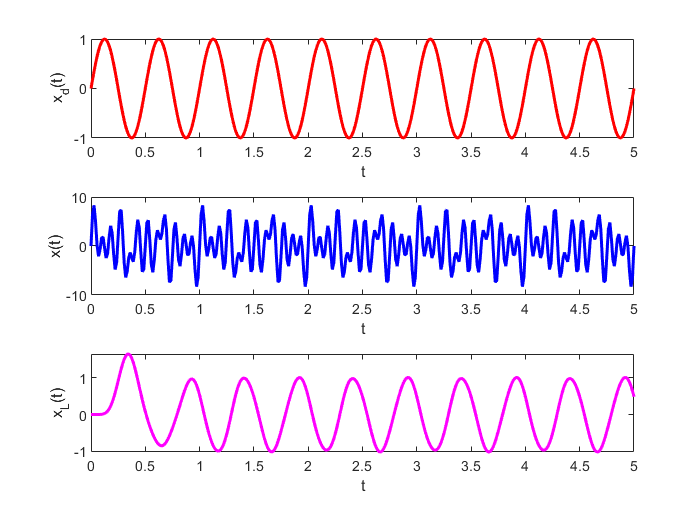


%vẽ tín hiệu ngõ ra
xL = filter(b,a,xn);

figure(3)
subplot(3,1,1);
plot(t,x1,'r-','linewidth',1.8);
xlabel('t'); ylabel('x_d(t)');

subplot(3,1,2);
plot(t,xn,'b-','linewidth',1.8);
xlabel('t'); ylabel('x(t)');

subplot(3,1,3);
plot(t,xL(1:length(t)),'m-','linewidth',1.8);
xlabel('t'); ylabel('x_L(t)');